clear; clc;

Seção inicial: definições do experimento:

% ranges de simulação
EbN0dB = 0:1:20;
EbN0 = 10.^(EbN0dB/10);
% Número de símbolos testados por amostra
Ns = 1e6;

% Vetores auxiliares para guardar os resultados
Pe = zeros(4, numel(EbN0dB)); % Probabilidade de erro (teórica)
SER = Pe; % Taxa de erro de símbolos (simulada)

item a: 2-PAM (BPSK)

for ii = 1:numel(EbN0)
    N0 = 1./EbN0(ii); % considerando Eb = 1
    sigma = sqrt(N0/2);
    
    % rodando o experimento
    s = 2*randi([0 1], Ns, 1) - 1; % vetor de Ns elementos de [-1 +1]
    r = s + sigma*randn(Ns,1); % sinal + ruído normal
    s_hat = sign(r); % equivale a verificar se o sinal está mais próximo de 1 ou -1
    
    % calculando resultados
    SER(1, ii) = mean(s~=s_hat);
    Pe(1, ii) = qfunc(sqrt(2*EbN0(ii)));
end

item b: 4-PAM

for ii = 1:numel(EbN0)
    N0 = 1./EbN0(ii); % considerando Eb = 1
    sigma = sqrt(N0/2);
    
    % rodando o experimento
    bits = randi([0 1], 2*Ns, 1); % geram-se 2*Ns bits
    sentIdx = bi2de(reshape(bits,[],2),'left-msb'); % convertem-se os bits em decimais (0,3)

    map = [-3 -1 1 3]; % map.^2 = [9 1 1 9]
    % Es = d^2 * E_hat^2 = 2*Eb = 2 ... mas E_hat é a média dos quadrados dos níveis em map
    d = sqrt(2/5); % Já que E_hat = 5

    s = d*map(sentIdx+1).'; % vetor de Ns elementos de d*[-3 a +3]
    r = s + sigma*randn(Ns,1); % sinal + ruído normal

    [~,recIdx] = min(abs(r - d*map),[],2); % retorna apenas o índice mínimo em cada linha
    
    % calculando resultados
    SER(2, ii) = mean(recIdx-1 ~= sentIdx);
    Pe(2, ii) = (3/2) * qfunc(sqrt((4/5)*EbN0(ii)));
end

item c: 4-QAM (QPSK)

for ii = 1:numel(EbN0)
    N0 = 1./EbN0(ii); % considerando Eb = 1
    sigma = sqrt(N0/2);
    
    % rodando o experimento
    bits = randi([0 1], 2*Ns, 1); % geram-se 2*Ns bits
    I = 2*bits(1:2:end)-1; % [-1 +1]
    Q = 2*bits(2:2:end)-1; % [-1 +1]

    s = I + 1j*Q; % sinal
    n = sigma*(randn(Ns,1) + 1j*randn(Ns,1)); % noise
    r = s + n;

    % calculando resultados
    SER(3, ii) = mean((sign(real(r))~=I) | (sign(imag(r))~=Q));
    q = qfunc(sqrt(2*EbN0(ii)));
    Pe(3, ii) = 2*q - q.^2;
end

item d: 2-FSK

for ii = 1:numel(EbN0)
    N0 = 1./EbN0(ii); % considerando Eb = 1
    sigma = sqrt(N0/2);
    
    % rodando o experimento
    b = randi([0 1], Ns, 1);
    s = [b==0, b==1];
    r = s + sigma*randn(Ns,2);
    [~,det]= max(r,[],2);

    % calculando resultados
    SER(4, ii) = mean(det-1 ~= b);
    Pe(4, ii) = qfunc(sqrt(EbN0(ii)));
end

Seção final: Plotando os gráficos:

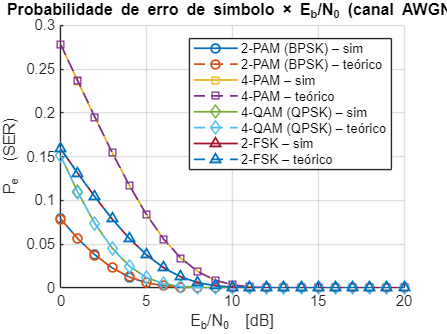

figure; hold on; grid on;
mods   = {'2-PAM (BPSK)','4-PAM','4-QAM (QPSK)','2-FSK'};
marks  = {'o','s','d','^'};

for m = 1:4
    semilogy(EbN0dB,SER(m,:),['-' marks{m}],'LineWidth',1.2);
    semilogy(EbN0dB,Pe (m,:),['--' marks{m}],'LineWidth',1.2);
end

xlabel('E_b/N_0  [dB]'); ylabel('P_e  (SER)');
legend( [strcat(mods,' – sim').', strcat(mods,' – teórico').'].', ...
    'Location','northeast');
title('Probabilidade de erro de símbolo × E_b/N_0 (canal AWGN)');